# Compare Entropy and Information Metrics

% This script introduces nearest neighbor methods for calculating
% entropy and mutual information.

## Initialize Workspace

% Clear everything:
clear all; close all force; clc;

% Path maintenance:
restoredefaultpath
addpath('matlab_tools')
addpath('project_tools')

## Steps 1 & 2: Create, Sample, and Plot a Synthetic Mixture Density

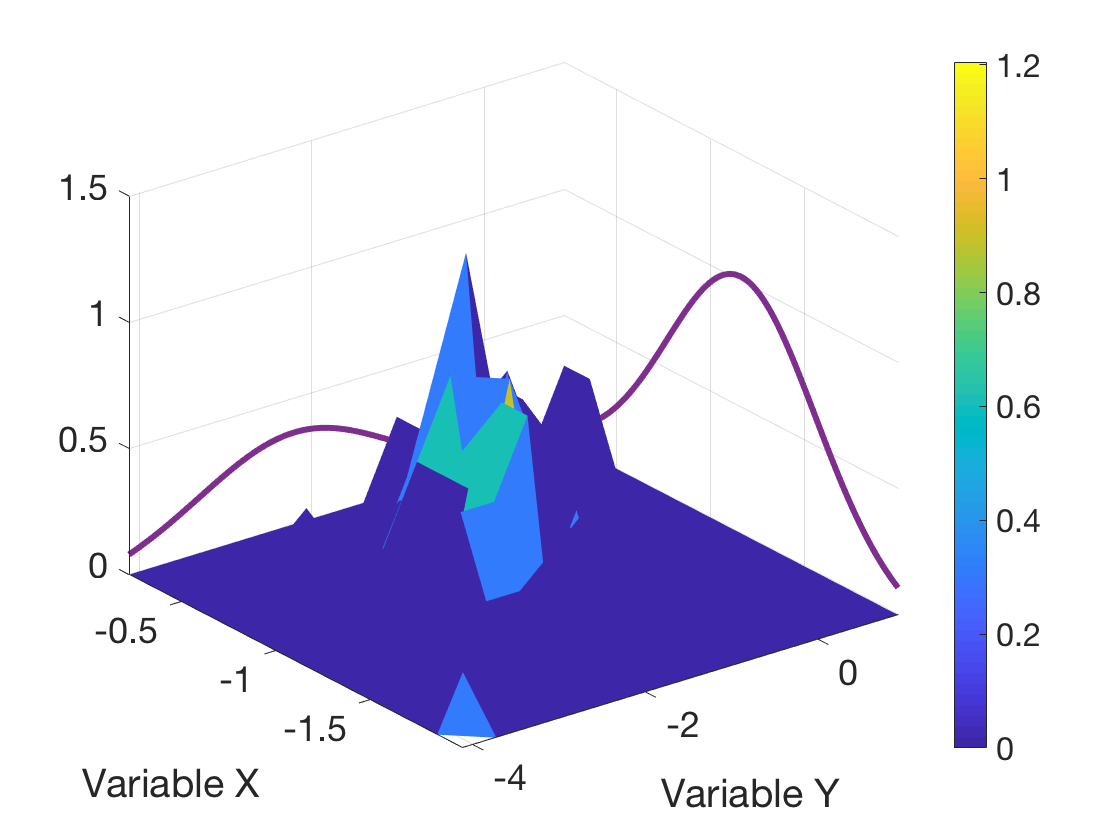

% How many kernels?
nKernels = 1;

% Which type(s) of kernel to use?
kernelType = 'Normal';

% Choose copula strength:
copulaParameter = 0.79;

% How many samples?
logSamples = 1.8;
nSamples = round(10^logSamples);

% How many histogram bins?
nBins = 14;

% Create joint densities:
jointDensity.marginal1 = create_mixture_density(nKernels,nMarginals,kernelType);
jointDensity.marginal2 = create_mixture_density(nKernels,nMarginals,kernelType);
jointDensity.param = copulaParameter;

% The section for sampling and plotting a joint distribution is 
% condensed to a single function to save space in this live script.
fignum = 1;
sample = section_sample_and_plot_joint(jointDensity,nSamples,nBins,fignum);

## Step 3: Entropy and Mutual Information Calculations

% True values for Gaussian case:
iTrue = 0/0;
hTrue = 0/0;
if nKernels == 1 && strcmpi(kernelType,'Normal')
    hTrue = 1/2 * log(2*pi*exp(1)*jointDensity.marginal1.params{1}(2)^2);
    iTrue = -1/2 * log(1-jointDensity.param^2);
end

% Discretize the sample into a fixed number of bins:
[iHist,hxHist,hyHist] = mutual_info_differential(X,Y,nBins);

% Discretize the sample into bins with fixed frequency:
[iHistFixed,hxHistFixed,hyHistFixed] = mutual_info_fixed_counts(sample(:,1),sample(:,2),nBins);

Undefined function or variable 'mutual_info_fixed_counts'.

% [histDensitiesFixedCount,histEdgesFixedCount] = hist1_fixed_sample(sample(:,1),nBins);  
% hFixedCount = -mean(log(histDensitiesFixedCount));

% Kozachenko_Leonenko with k=1:
hKL = Kozachenko_Leonenko(sample(:,1));

% k-Neighbor calculation:
[ikNN,hxkNN,hyKNN] = knn_info(sample(:,1),sample(:,2),1);

% Screen report:
fprintf(['Estimates of Entropy with %d bins with %d samples: \n' ...
    '--- Analytic:              H = %f [nats] \n' ...
    '--- Fixed Number of Bins:  H = %f [nats] \n' ...
    '--- Fixed Counts per Bin:  H = %f [nats] \n'...
    '--- kNN (k = 1):           H = %f [nats] \n',...
    '--- Kozachenko-Leonenko:   H = %f [nats]'],...
    nBins,nSamples,hTrue,hHist,hHistFixed,hkNN,hKL);
% Screen report:
fprintf(['Estimates of Information with %d bins with %d samples: \n' ...
    '--- Analytic:              H = %f [nats] \n' ...
    '--- Fixed Number of Bins:  H = %f [nats] \n' ...
    '--- Fixed Counts per Bin:  H = %f [nats] \n'...
    '--- kNN (k = 1):           H = %f [nats] \n',...
    '--- Kozachenko-Leonenko:   H = %f [nats]'],...
    nBins,nSamples,iTrue,iHist,iHistFixed,ikNN,iKL);

## Step 4: As a Function of Sample Size and Bin Counts

% Increasing sample size:
nSampleSizes = 10;
sampleSizes = unique(round(logspace(1,3,nSampleSizes)));

% Increasing number of histogram bins:
nBinCounts = 15;
binCounts = unique(round(logspace(1,2,nBinCounts)));

% Number of resampling experiments:
nResamples =11;

% Initialize storage:
hFixedSize = zeros(nSampleSizes,nBinCounts,nResamples)./0;
hFixedCount = zeros(nSampleSizes,nBinCounts,nResamples)./0;
hkNN1 = zeros(nSampleSizes,nBinCounts,nResamples)./0;

% Loop through resampling experiments:
for r = 1:nResamples
    
    % Initialize progress bar:
    totalCalcs = nSampleSizes * nBinCounts;
    timerCalcs = round(linspace(1,totalCalcs,50));
    calcCount = 0;
    fprintf('Sample #%d of %d ... \n',r,nResamples);
    fprintf(strcat(repmat('.',[1,50]),'\n')); tic;
    
    % Loop through sample sizes and bin counts:
    for c = 1:nBinCounts
        for s = 1:nSampleSizes
            
            % Screen report:
            calcCount = calcCount + 1;
            if ismember(calcCount,timerCalcs); fprintf('.'); end
            
            % Draw one master sample from the mixture density:
            resample = sample_mixture_density(jointDensity.marginal1,sampleSizes(s));
      
            % Discretize the sample into a fixed number of bins:
            [histCountsFixedSize,histEdgesFixedSize] = hist1(resample,binCounts(c));
            binWidth = histEdgesFixedSize(2) - histEdgesFixedSize(1);
            histProbsFixedSize = histCountsFixedSize / sampleSizes(s);
            histDensitiesFixedSize = histProbsFixedSize / binWidth(1);
            iNonZero = find(histCountsFixedSize>0);
            hFixedSize(s,c,r) = -histProbsFixedSize(iNonZero)' * log(histDensitiesFixedSize(iNonZero));
            
            % Discretize the sample into bins with fixed frequency:
            [histDensitiesFixedCount,histEdgesFixedCount] = hist1_fixed_sample(resample,binCounts(c));
            hFixedCount(s,c,r) = -mean(log(histDensitiesFixedCount));
            
            % Entropy calculation:
            hkNN1(s,c,r) = knn_entropy(resample);
            
        end % s-loop
    end % c-loop
    
    % Screent report:
    fprintf('time = %f[s] \n\n',toc);
    
end % r-loop

Sample #1 of 11 ... 


..................................................


..................................................

time = 0.740168[s] 



Sample #2 of 11 ... 


..................................................


..................................................

time = 0.404380[s] 



Sample #3 of 11 ... 


..................................................


..................................................

time = 0.550944[s] 



Sample #4 of 11 ... 


..................................................


..................................................

time = 0.534893[s] 



Sample #5 of 11 ... 


..................................................


..................................................

time = 0.567900[s] 



Sample #6 of 11 ... 


..................................................


..................................................

time = 0.473268[s] 



Sample #7 of 11 ... 


..................................................


..................................................

time = 0.671656[s] 



Sample #8 of 11 ... 


..................................................


..................................................

time = 0.740341[s] 



Sample #9 of 11 ... 


..................................................


..................................................

time = 0.684725[s] 



Sample #10 of 11 ... 


..................................................


..................................................

time = 0.484547[s] 



Sample #11 of 11 ... 


..................................................


..................................................

time = 0.263285[s] 



## Step 4.1: Plot Convergence

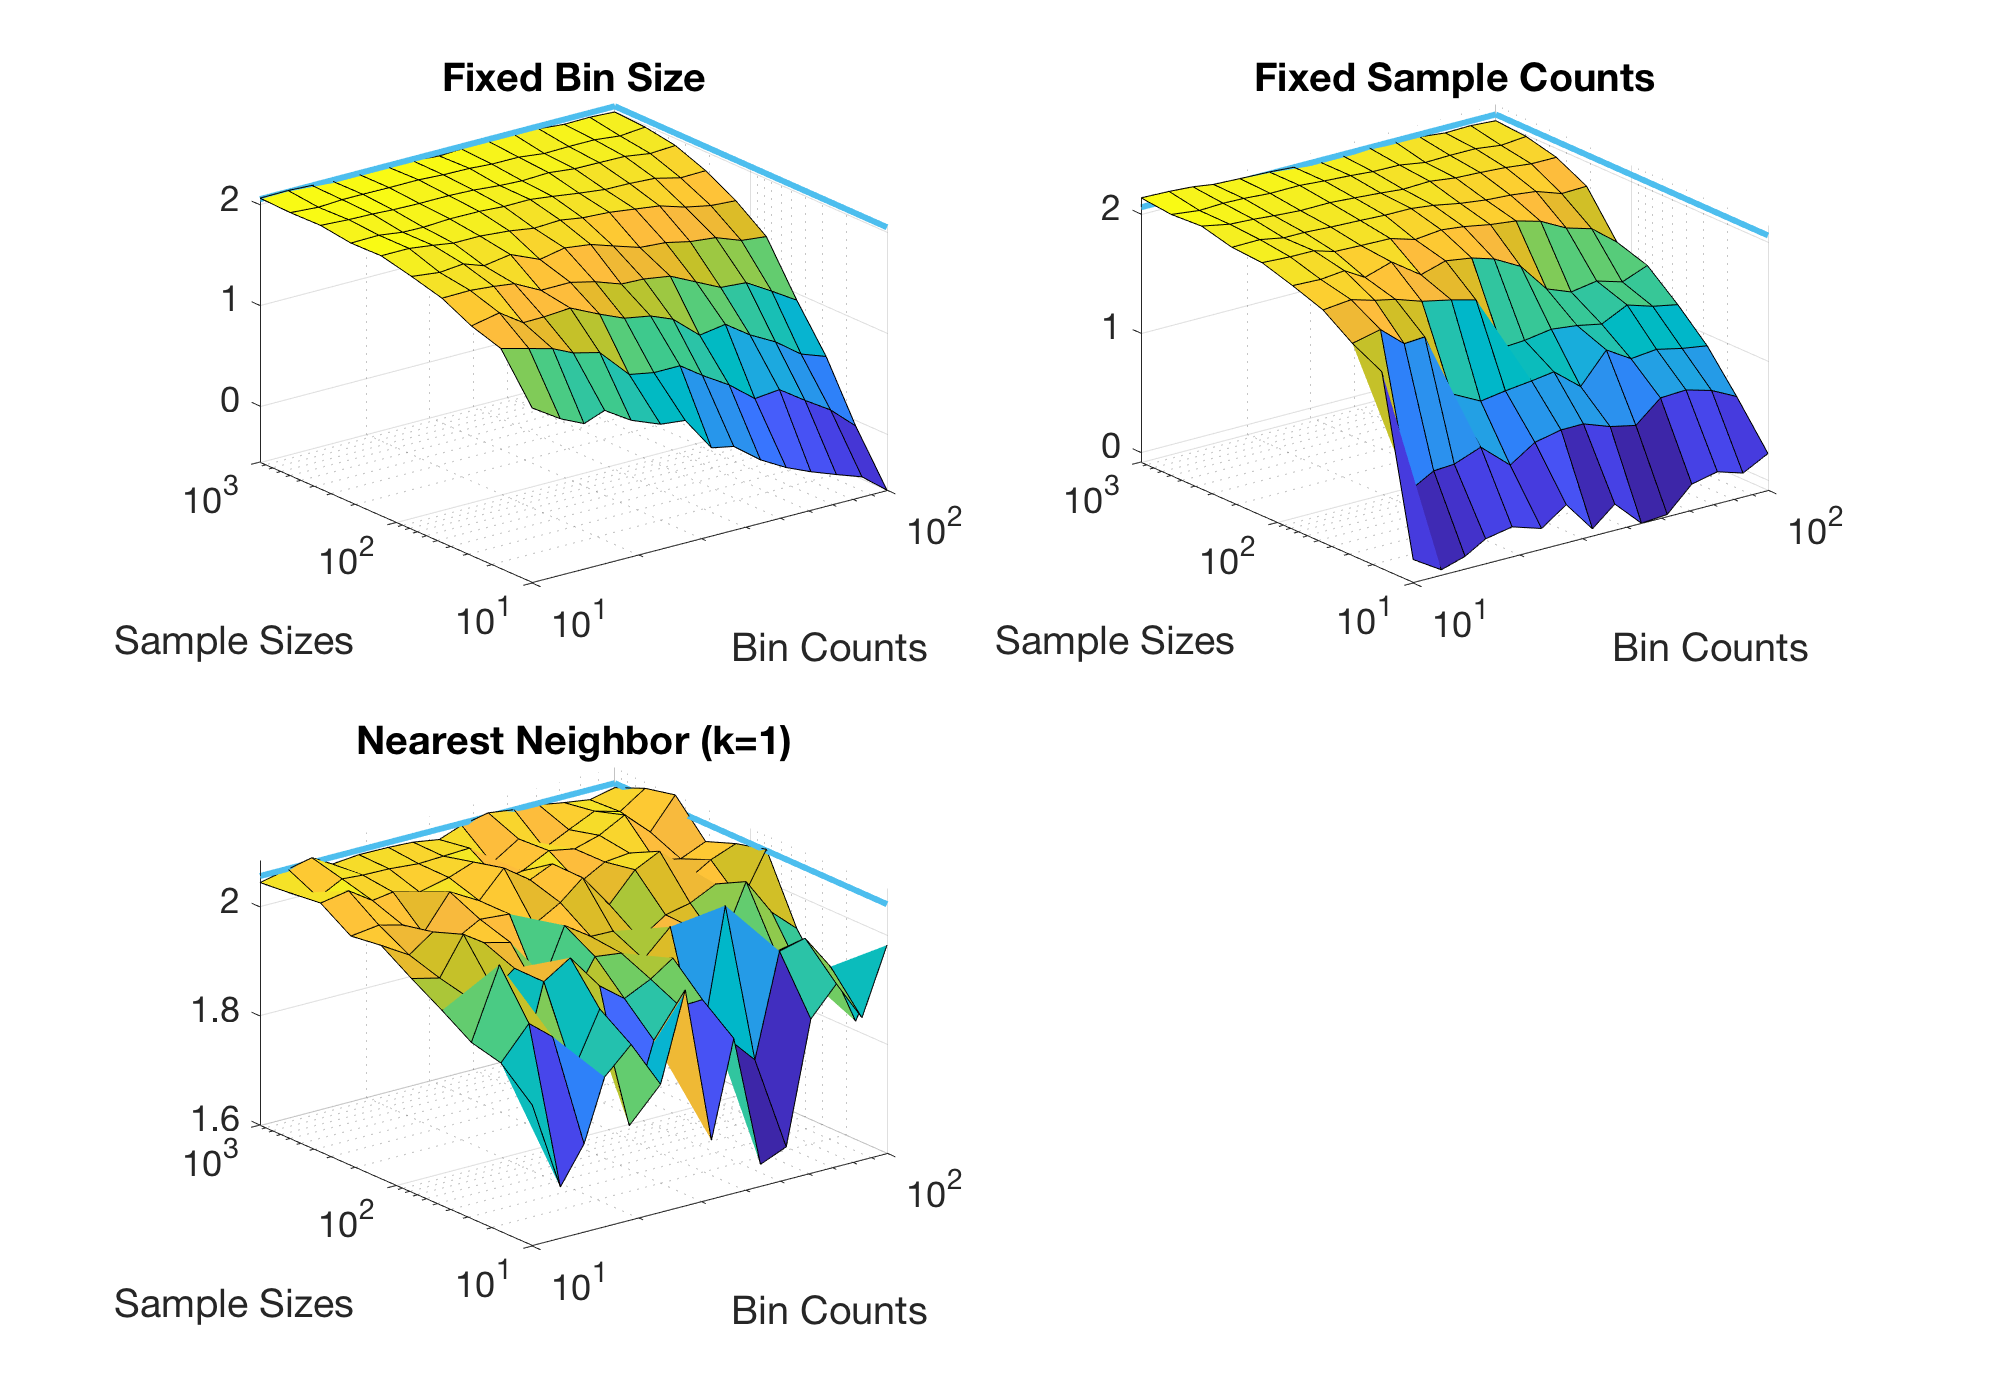

% Initialize a figure for plotting entropy estimates:
colors = grab_plot_colors; 
fignum = 2; figure(fignum); close(fignum); figure(fignum);
set(gcf,'position',[1,1,1000,700]); 

% Plot discrete entropies:
subplot(2,2,1)
surf(binCounts,sampleSizes,mean(hFixedSize,3)); hold on;
plot3(repmat(binCounts(end),[1,nSampleSizes])',sampleSizes,repmat(hTrue,[1,nSampleSizes])','linewidth',3,'color',colors(4,:)); 
plot3(binCounts,repmat(sampleSizes(end),[nBinCounts,1]),repmat(hTrue,[nBinCounts,1]),'linewidth',3,'color',colors(4,:)); 

% Aesthetics:
set(gca,'Xscale','log','Yscale','log')
xlabel('Bin Counts')
ylabel('Sample Sizes')
title('Fixed Bin Size')
set(gca,'fontsize',18);
grid on;

% Plot differential entropies:
subplot(2,2,2)
surf(binCounts,sampleSizes,mean(hFixedCount,3));hold on;
plot3(repmat(binCounts(end),[1,nSampleSizes])',sampleSizes,repmat(hTrue,[1,nSampleSizes])','linewidth',3,'color',colors(4,:)); 
plot3(binCounts,repmat(sampleSizes(end),[nBinCounts,1]),repmat(hTrue,[nBinCounts,1]),'linewidth',3,'color',colors(4,:)); 

% Aesthetics:
set(gca,'Xscale','log','Yscale','log')
xlabel('Bin Counts')
ylabel('Sample Sizes')
title('Fixed Sample Counts')
set(gca,'fontsize',18);
grid on;

% Plot differential entropies:
subplot(2,2,3)
surf(binCounts,sampleSizes,mean(hkNN1,3));hold on;
plot3(repmat(binCounts(end),[1,nSampleSizes])',sampleSizes,repmat(hTrue,[1,nSampleSizes])','linewidth',3,'color',colors(4,:)); 
plot3(binCounts,repmat(sampleSizes(end),[nBinCounts,1]),repmat(hTrue,[nBinCounts,1]),'linewidth',3,'color',colors(4,:)); 

% Aesthetics:
set(gca,'Xscale','log','Yscale','log')
xlabel('Bin Counts')
ylabel('Sample Sizes')
title('Nearest Neighbor (k=1)')
set(gca,'fontsize',18);
grid on;